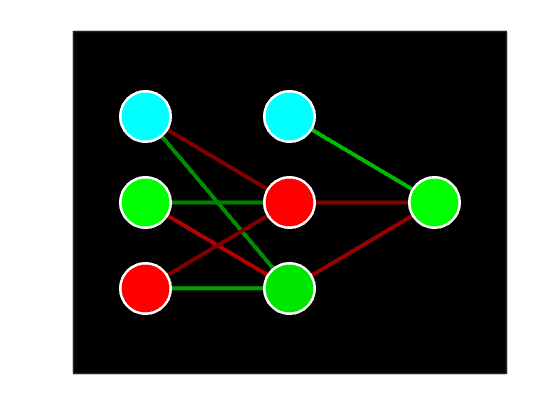

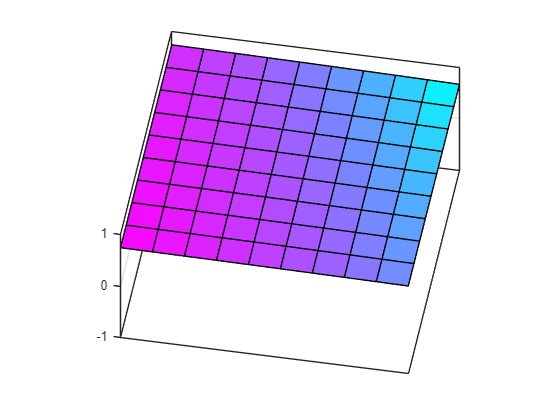

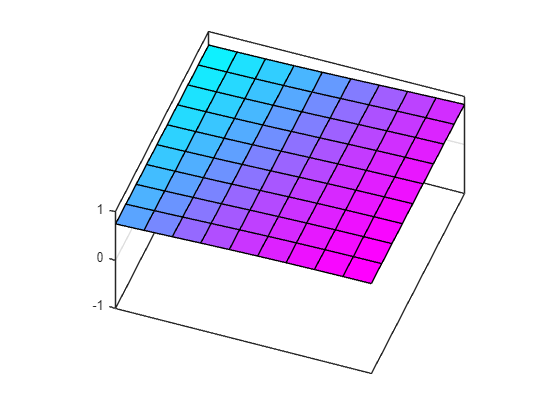

clf
clear
close all
set(groot,'defaultAxesXTick',[],'defaultAxesXTickMode','manual')
set(groot,'defaultAxesYTick',[],'defaultAxesYTickMode','manual')
fig1 = figure;
fig2 = figure;
fig3 = figure;
ax = axes(fig1);
ay = axes(fig2);
az = axes(fig3);

%design dense neural network
designVector = [2,2,1];

%parameters for the algorithm
%define the ammount of training samples in the dataset
numSamples = 60;
lern_rate = 0.3;
epochs = 100;
minibatch_size = 1;

%create dataset and according labels
x = randi(2,1,numSamples)-1;
y = randi(2,1,numSamples)-1;
Targets = double(xor(x,y));

%set zeros to -1 for tanh usage
x(x==0) = -1;
y(y==0) = -1;
Targets(Targets==0) = -1;


%set up presets for algorithm
Inputs = [x;y];
weightsCell = genWeightsNN(designVector);           %generate random weights
averageLoss = zeros(1,epochs);
epochalLoss = 0;
previous_gradientCell = weightsCell;

totalDCDrawTime = 0;
totalNNDrawTime = 0;
totalCalcTime = 0;

for e = 1:epochs
    for k = 1:numSamples
        % functions that coordinate the neural network
        [Outputs,hiddenOutputsCell] = feedForwardNN(Inputs(:,k),weightsCell,'tanh');
        [gradientCell,loss] = backpropNN(Inputs(:,k),Outputs,hiddenOutputsCell,weightsCell,Targets(k),'tanh');
        %sum up loss during whole dataset even while we update while going trogh
        epochalLoss = epochalLoss + loss;
        %update weights
        for i = 1:length(designVector) - 1
            weightsCell{i} = weightsCell{i} - lern_rate.*(gradientCell{i} + previous_gradientCell{i}.*0.9);
        end
        %store gradients for usage in the momentum term in the next
        previous_gradientCell = gradientCell;
    end
    averageLoss(e) = epochalLoss/numSamples;
    epochalLoss = 0;

    %plot the decision surface
    res = 10;
    xx = linspace(-1,1,res);
    yy = linspace(1,-1,res);
    [X,~] = meshgrid(xx);
    [~,Y] = meshgrid(yy);
    Ot = zeros(res);
    for u = 1:res
        for j = 1:res
            % 3D-Figure
            Inpuut = [Y(u,j);X(u,j)];
            Ot(u,j) = feedForwardNN(Inpuut,weightsCell);
        end
    end
    surf(ay,Y,X,Ot);
    ay.ZLim = [-1 1];
    ay.DataAspectRatio = [1 1 2];
    ay.Box = 'on';
    cmp = colormap('cool');
    ay.Colormap = cmp;
    ay.View = [10+e*0.1,45];
    ay.Projection = 'orthographic';

    %draw neural network
    [storedPlot,weightsColorMap,storedScatter] = drawNN(designVector,Inputs(:,1),Outputs,hiddenOutputsCell,weightsCell);
    storedPlot(ax);
    colororder(ax, weightsColorMap);
    hold(ax, 'on');
    storedScatter(ax);
    ax.XLim = [0.5 length(designVector)+0.5];
    ax.YLim = [0 max(designVector)+2];
    ax.Color = 'k';
    pause(10e-10)

end

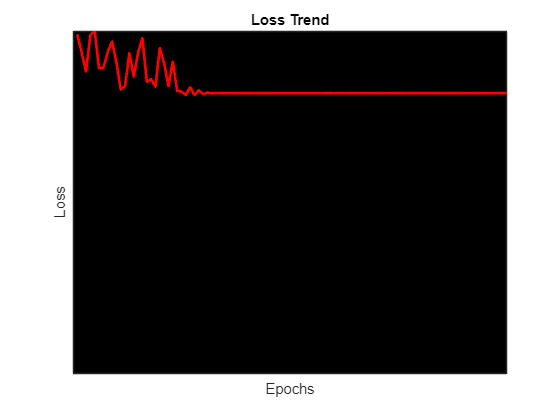


%plot evolution of loss
plot(az,1:e,nonzeros(averageLoss),'LineWidth',2,'Color','r')
az.YLim = [0,max(averageLoss)];
az.YLabel.String = 'Loss';
az.XLabel.String = 'Epochs';
az.Title.String = 'Loss Trend';
az.Color = 'k';


%restet groot properties
reset(groot)